# 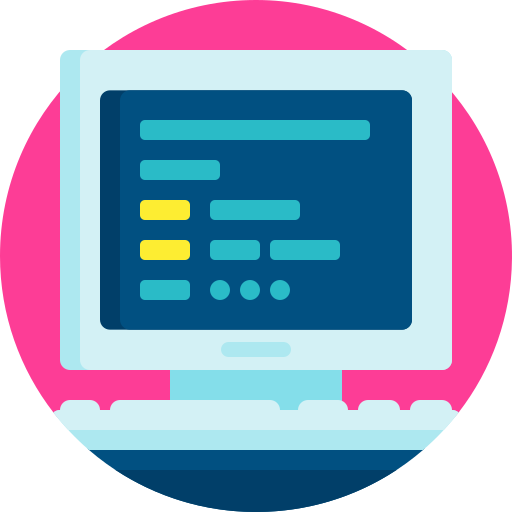

# Virtual Lab 8 - Trajectory generation of a 2R robot arm

### This Virtual Lab covers Chapter 7 notes.

- This Virtual Lab will require both pen-on-paper work, as well as the use of MATLAB coding. The intention is to be able to solve the problems on paper (as you would in a Test/Exam) and then ratify the result using MATLAB.

- Make sure to save this file somewhere where you can access it again later, e.g. Google Drive/OneDrive/MATLAB Drive (or on your PC if you are working on a laptop). 

- This live script is intended to be used with the code shown. Select the `VIEW` tab and switch to `Output on right`.

- Each Section of this Live Script must be run individually. You can run Sections by using the `Run Section` button under the `LIVE EDITOR` ribbon (at the top of the screen), or using CNTL+ENTER (Windows) or CMD+ENTER (macOS).

Virtual Lab 8 will build on the experience that you have gained from previous Virtual Labs. It is now assumed that you are comfortable with the 2R robot arm and the accompanying MATLAB `rigidBodyTree` functionality.

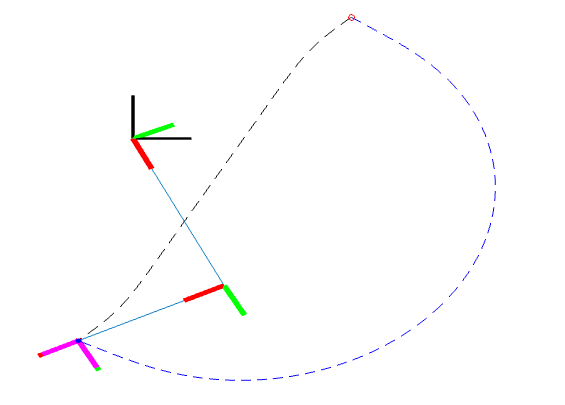

*Figure 1: Two different end-effector position trajectories that have common start and end points. The black trajectory is the result of a task space trapezoidal velocity profile, whereas the blue trajectory is a result of a joint space trapezoidal velocity profile.*

## Robot setup

Set up your 2R robot arm such that the link lengths are $l_1$=0.4m and $l_2=0.3$m, with joint rotations occurring about the $\hat{\bf z}$-axis. Set the joint home positions such that the end-effector is placed at $^W{\bf p}=[0.4~0.3]^T$. Use the same naming scheme as in the previous practicals and visualise the robot configuration to ensure that you have set everything up correctly. 

%Robot setup code here
l1_ = 0.4;
l2_ = 0.3;

robot = rigidBodyTree("DataFormat","column");
manipulatorBase = rigidBody('manipulatorBase');
%joint1
joint1 = rigidBodyJoint('joint1','revolute');
joint1.JointAxis = [0 0 1];
joint1.HomePosition = 0;
p_joint1 = [0, 0, 0];
tform = trvec2tform(p_joint1);
setFixedTransform(joint1,tform)
manipulatorBase.Joint = joint1;
addBody(robot,manipulatorBase,'base');
%joint2 and link1
link1 = rigidBody('link1');
joint2 = rigidBodyJoint('joint2','revolute');
joint2.JointAxis = [0 0 1];
joint2.HomePosition = pi/2;
p_joint2 = [l1_, 0, 0];
tform2 = trvec2tform(p_joint2);
setFixedTransform(joint2,tform2);
link1.Joint = joint2;
addBody(robot,link1,'manipulatorBase');
%link2 and end-effector
link2 = rigidBody('link2');
joint3 = rigidBodyJoint('joint3');
tform3 = trvec2tform([l2_, 0, 0]);
setFixedTransform(joint3,tform3);
link2.Joint = joint3;
addBody(robot,link2,'link1');

Use `show `to ensure that the robot is correctly configured.

%Add code here


We will use $\bf x$ again as our generalised coordinate vector. Set $\bf x$ equal to the home configuration of the robot.

%Add code here


We will again make use of the closed-form (algebraic) inverse kinematic solution from **Virtual Lab 7** using the symbolic `solve` function. 

syms px py alpha beta real
syms l1 l2 positive

[alpha,beta] = solve( px==l1*cos(alpha)+l2*cos(alpha+beta),py==l1*sin(alpha)+l2*sin(alpha+beta),alpha,beta);
alpha = simplify(expand(alpha));
beta = simplify(expand(beta));

We will use this later on in the Virtual Lab, so do not overwrite variables `alpha `and `beta`!

## Trapezoidal velocity profiles

Trapezoidal velocity profiles are a useful means of defining trajectories when there are velocity and/or acceleration constraints that must be adhered to. 

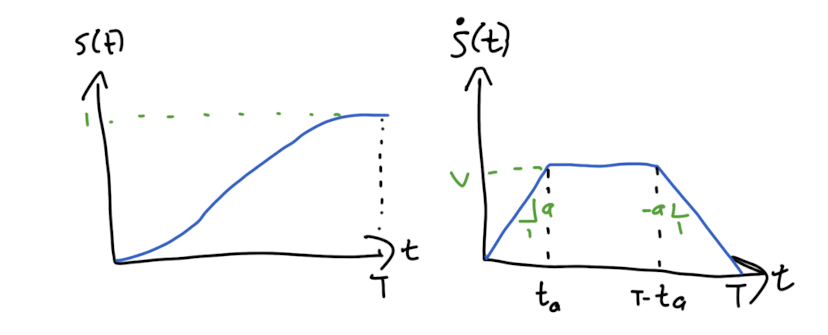

*Figure 2: Sketch of the position and velocity time-scaling trajectories that result from a trapezoidal velocity profile.*

Our task will be to command the robot such that the end-effector moves from the initial position of $^W{\bf p}=[0.4 ~0.3]^T$  to $^W{\bf p}^*=[-0.1 ~-0.5]^T$ in $1$ second. 

p_start = [0.4 0.3]';   %starting position of end-effector
p_end = [-0.1 -0.5]';   %end position of end-effector

Although the manipulator arm operates in a 2D translational space, we will first determine the time-scaling function that allows us to move the robot end-effector from the start point to the end point.

With reference to *Figure 2*, given velocity and acceleration constraints of $v$ and $a$ respectively, the position trajectory that results from a trapezoidal velocity profile is


$$s(t) =\left\{
        \begin{array}{ll}
          \frac{1}{2}at^2, &  0\leq t\leq \frac{v}{a}, \\
           vt-\frac{v^2}{2a}, & \frac{v}{a} < t \leq T-\frac{v}{a}. \\
           \frac{2avT-2v^2-a^2(t-T)^2}{2a}, & T-\frac{v}{a} < t \leq T. \\
        \end{array}
    \right.$$


where $T$ is the completion time of the trajectory, and $t\in [0,T]$ is the time parameter in seconds. 

#### Question 1: Given the symmetrical requirement of trapezoidal velocity profiles, what is the largest possible value of $t_a=\frac{v}{a}$?

%Code block (if required)


#### Question 2: What is the requirement on $v$ and $a$ to ensure that an admissible trajectory exists?

%Code block (if required)


### Coding a trapezoidal velocity time-scaling function.

Write a trapezoidal velocity trajectory function, $s(t)$, that has the following inputs 

- a desired completion time, T,

- a maximum acceleration, $\ddot{s}_{max}=a$,

The function must output the time-scaling trajectory and corresponding derivatives. You must use a step size of $\Delta T=1\times10^{-3}$ seconds. 

Other considerations:

- If the specified maximum acceleration and completion time is incompatible, a display prompt should indicate this (see [`disp`](https://www.mathworks.com/help/matlab/ref/disp.html) function). 

- You can assume that the time-scaling function adheres to $s(0)=\dot{s}(0)=\dot{s}(T)=0$ and $s(T)=1$.

- Due to the fact that we are using a discretised profile, there will be certain combinations of input parameters that result in *minor* kinks where phases merge. This can be ignored.

- The desired completion time, $T$, can only have up to 3 decimal places. You will need to use [`round`](https://www.mathworks.com/help/matlab/ref/round.html) to enforce this in the function.

You can write the function in a separate `MATLAB .m` file (saved in the same folder as VirtualLab8`.mlx`) or at the bottom of this live script. The function should have the general structure and naming convention as shown below:

Once you have written your function call it in the code block below, using the following configuration

- $a=4$ $m/s^2$,

- $T=1$second.

T = 1;
a = 4;
[s,ds,dds] = getTrapezoidalTimeScalingFunction(T,a);

Plot the three profiles using `subplot`*,* and set the figure title as your name+student number using `sgtitle` (see *Figure 3* below as an example).

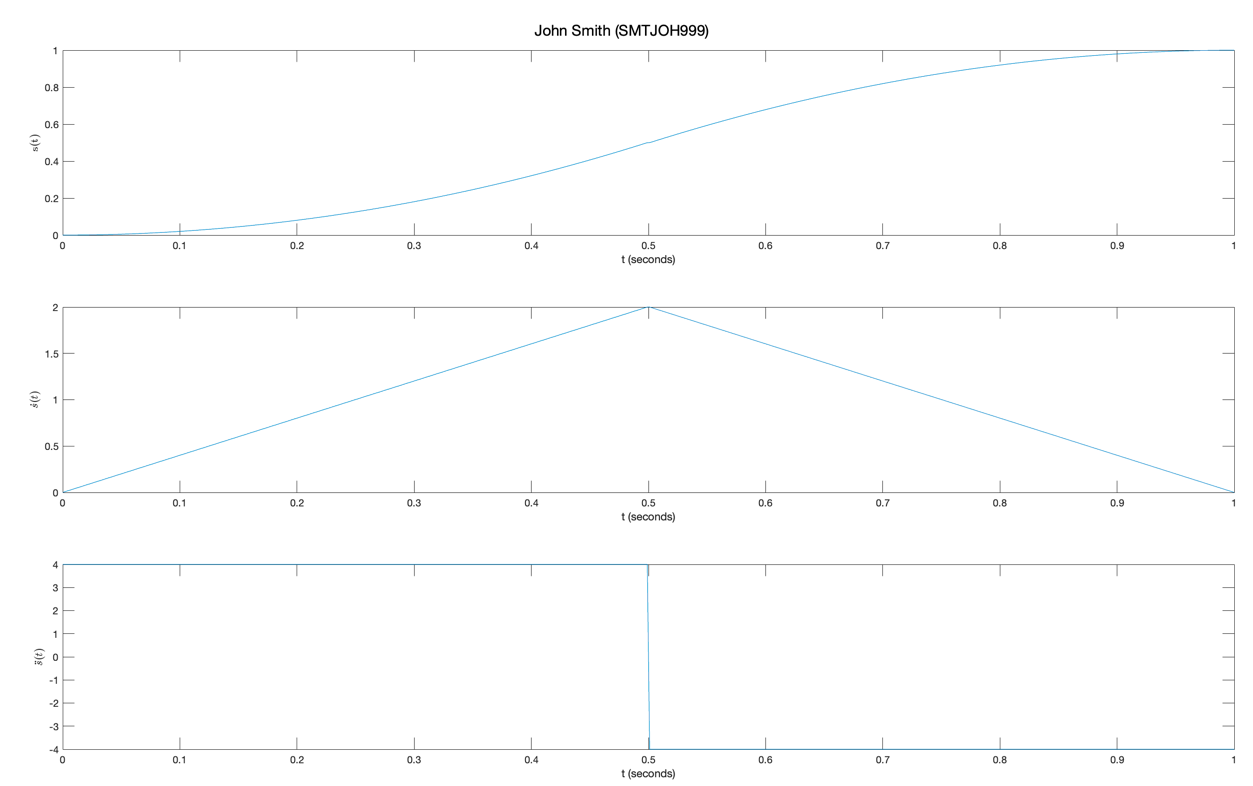

*Figure 3: An example of using subplot to display the position, velocity and acceleration trajectories.*

t = linspace( 0,T,length(s) );

figure(1),clf,shg,hold on
subplot(3,1,1),plot(t,s),xlim([0 T]),ylabel('s(t)',Interpreter='latex'),xlabel('t (seconds)')
subplot(3,1,2),plot(t,ds),xlim([0 T]),ylabel('$\dot{s}(t)$',Interpreter='latex'),xlabel('t (seconds)')
subplot(3,1,3),plot(t,dds),xlim([0 T]),ylabel('$\ddot{s}(t)$',Interpreter='latex'),xlabel('t (seconds)')
sgtitle('John Smith (SMTJOH999)') %change this!
shg

#### Question 3: Upload your `subplot` figure (jpeg/png) from above.

If your answer is correct, it should match that of *Figure 3*.

#### Question 4: What is the minimum possible completion time for this particular trajectory, given the acceleration limit?

*Hint: test your minimum completion time with your trapezoidal trajectory generator function.*

%Code block (if required).


Recalling that  


$${{\bf X}}(s)={{\bf X}_0}+s\left({{\bf X}_T}-{{\bf X}_0}\right),$$
 

we can now relate the time-scaling function to the task-space goal of moving the end-effector from $^W{\bf p}$ to $^W{\bf p}^*$ over one second. In this particular instance, ${{\bf X}_0}={^W{\bf p}}$ and ${{\bf X}_T}={^W{\bf p}^*}$. From this we can also determine the corresponding derivatives.

#### Question 5: Using the time-scaling function, upload a MATLAB-generated image of the position, velocity, and acceleration profiles of the end-effector when moving from $^W{\bf p}=[0.4 ~0.3]^T$  to $^W{\bf p}^*=[-0.1 ~-0.5]^T$ over 1 second.

%Add code here


## Task space trajectory following

Adjust your animation code from **Virtual Lab 7** to use the time-scaling function (and appropriate scaling) to set the end-effector position using inverse kinematics. Remember that you have already defined the `robot` object and inverse kinematic mapping at the beginning of the Virtual Lab.

- Plot the 2D path that the end-effector must take using a black dashed line. 

- Use a completion time of $T=1$second. 

- Your trajectory will have time increments of $\Delta T=0.001$seconds, but update the plot every 0.1 seconds (every $100^{\text{th}}$ iteration). 

- Use the same starting configuration and maximum acceleration as above.

%Add code here


You should see the end-effector move smoothly from the start configuration to the end configuration in a straight line as shown below

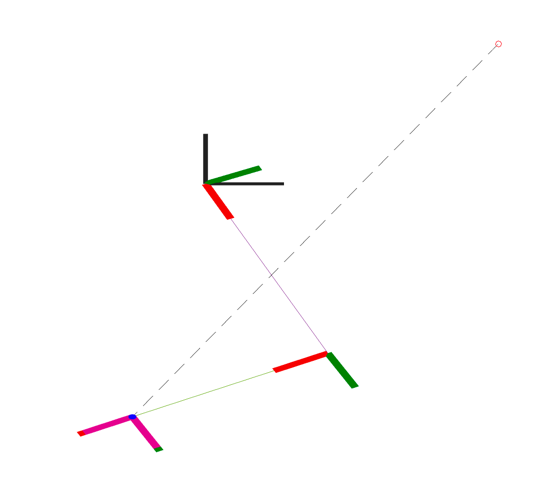

*Figure 4: End-effector reaching end position after moving along task space trajectory.*

#### Question 6: Indicate whether a cubic polynomial could complete this trajectory in a shorter timespan.

Add to your animation code in order to record a .mp4 of the animation. This can be done by adding

before the `loop`, adding

after `drawnow`, and adding 

after the loop.

#### Question 7: Upload a .mp4 of the end-effector moving along the defined trajectory.

## Configuration space trajectory following

Based on **Virtual Lab 7**, it should not be surprising that we can define and follow trajectories within the task space. What is less obvious is whether any workspace trajectory can be followed given actuator limitations (e.g. joint rate and acceleration limits). 

If we are not concerned with the exact path that the end-effector takes, and are only concerned with the start and endpoints, we can rather develop a configuration (joint) space trajectory using trapezoidal velocity profiles (and our known actuator limits), in order to ensure that our robot can always follow the path. We can start by mapping the start and end points of the task space trajectory into the configuration space.

x0 = homeConfiguration(robot);

px = p_end(1);
py = p_end(2);
alpha_ = eval(alpha);
beta_ = eval(beta);

xT = [alpha_(1) beta_(1)]'; %we will use the first set of solutions.

 x0 and xT now define the start and end configurations of our joint space trajectory and we can now use a trajectory generation routine to link these start and end configurations. Note that regardless of the specific type of trajectory, once our robot configuration is ${\bf x}_T$, our end-effector position will be at $^W{\bf p}^*$ by definition of our unique forward kinematic relationship

${\bf X}_T={^W{\bf p}^\ast}={\bf\kappa}({\bf x}_{T})$.

Similarly, $x_0$ will always map to ${^W{\bf p}=[0.4~0.3]^T$, based on the use of the `homeConfiguration `in the code block above. 

We will now use our time-scaling function (and appropriate scaling) to generate a trajectory for both joint angles. Adjust your visualisation code from before to set the required joint angles directly based on the generated trajectory (no longer using inverse kinematics, but using the start and end configurations from above as your start and end points for the trajectory generator). 

- Plot the path that the end-effector takes using a blue dashed line. 

- Also plot the end-effector position trajectory from the previous question (in a black dashed line). 

- Your trajectory will have time increments of $\Delta T=0.001$seconds, but update the plot every 0.1 seconds (every $100^{th}$ iteration). 

- Use a completion time of $T=1$second. 

- Use an angular acceleration limit of $a=20$rad/s$^2$ for both joint angles.   

%Add code here


If your simulation is correct, the final configuration and image should match that of *Figure 1 *and the end-effector should move smooth smoothly along the blue path.

#### Question 8: Upload a .mp4 of the animation in Amathuba.

#### Question 9: Upload your Virtual Lab .mlx in Amathuba.